clear;clc;

% load parameters
par = importdata('par_scg.txt');
par = par.data;
n_E = par(4);
n_I = par(5);

% initial values
y0 = zeros(n_E+n_I+6, 1);
y0(1) = 1;
y0(n_I+n_E+2) = 100;
y0(n_I+n_E+3) = 1000;

tmax = 100;
tspan = 0:0.1:tmax;

[~, y] = ode45(@ODE_SCG, tspan, y0, [], par);

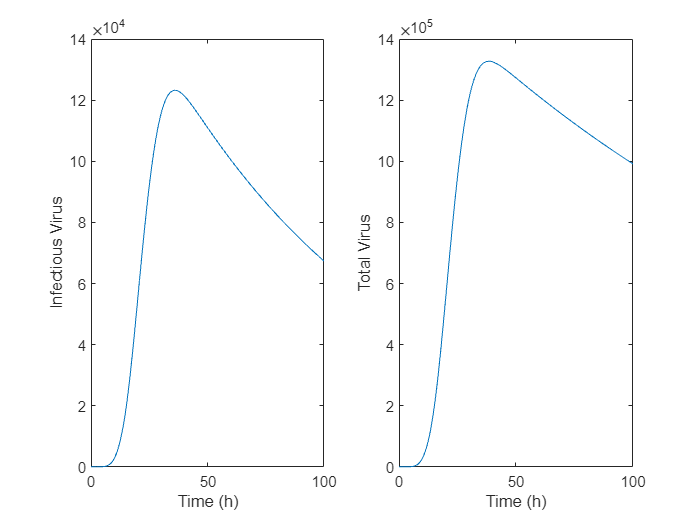

figure;
subplot(1, 2, 1);
plot(tspan, y(:, n_E+n_I+2));
xlabel('Time (h)'); ylabel('Infectious Virus');
subplot(1, 2, 2);
plot(tspan, y(:, n_E+n_I+3));
xlabel('Time (h)'); ylabel('Total Virus');

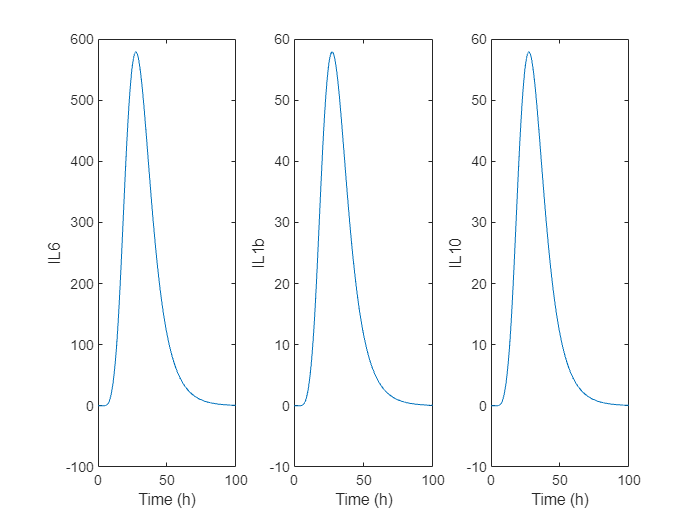


figure;
subplot(1, 3, 1);
plot(tspan, y(:, n_E+n_I+4));
xlabel('Time (h)'); ylabel('IL6');
subplot(1, 3, 2);
plot(tspan, y(:, n_E+n_I+5));
xlabel('Time (h)'); ylabel('IL1b');
subplot(1, 3, 3);
plot(tspan, y(:, n_E+n_I+6));
xlabel('Time (h)'); ylabel('IL10');